## Project software utilities

These are code snippets that help you use ISETCam to read and analyze the Google Pixel modeling project.  Make sure you have a done a recent 'git pull' of the ISETCam and psych221 repository.

### Reading DNG files:  ieDNGRead

We have functions to help you read a DNG (Adobe digital negative) file.  This is the format for the linear camera data. To just read the data and the header, you can use ieDNGRead.

% This file is checked into the repository, so we use it as an example
fname = 'mcc-Centered.dng';

img = ieDNGRead(fname);  % Read the image data 
[img, info] = ieDNGRead(fname); % The image data and the header information
info

info = struct with fields:
                     Filename: '/Users/wandell/Documents/MATLAB/isetcam/data/images/rawcamera/MCC-centered.dng'
                  FileModDate: '29-Sep-2020 21:14:49'
                     FileSize: 11066430
                       Format: 'tif'
                FormatVersion: []
                        Width: 672
                       Height: 504
                     BitDepth: 24
                    ColorType: 'YCbCr'
              FormatSignature: [73 73 42 0]
                    ByteOrder: 'little-endian'
               NewSubFileType: 1
                BitsPerSample: [8 8 8]
                  Compression: 'JPEG'
    PhotometricInterpretation: 'YCbCr'
                 StripOffsets: 146816
              SamplesPerPixel: 3
                 RowsPerStrip: 504
              StripByteCounts: 55654
                  XResolution: []
                  YResolution: []
               ResolutionUnit: 'Inch'
                     Colormap: []
          PlanarConfiguration:

[~, onlyInfo] = ieDNGRead(fname,'only info',true); % For speed: only the header information

% Read a reduced form of the header that includes only four parameters
[~, simpleInfo] = ieDNGRead(fname,'simple info',true);
[~, simpleInfo] = ieDNGRead(fname,'only info',true, 'simple info', true)

simpleInfo = struct with fields:
        isoSpeed: 64
    exposureTime: 0.0334
      blackLevel: [1023 1023 1022 1022]
     orientation: 6


### Reading DNG files and creating a sensor:  sensorDNGRead

This code returns an ISETCam sensor with the linear data from a DNG file. The parameters of the sensor match (generally) the properties of the Sony IMX363 sensor that is widely used in industry. 

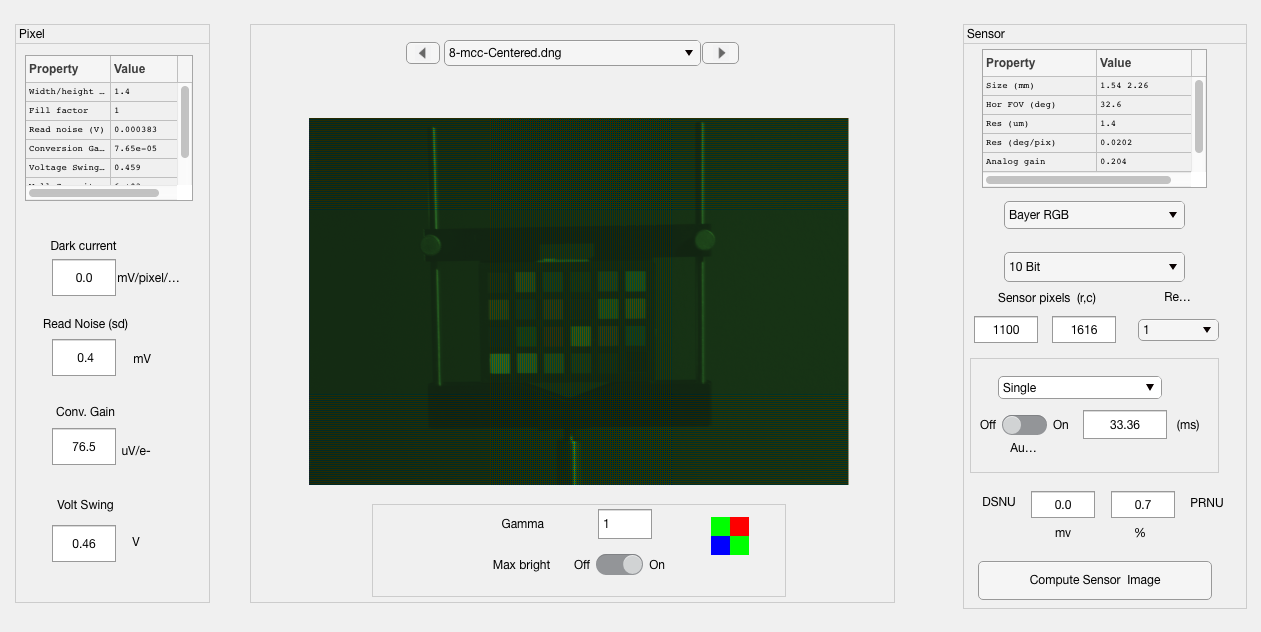

fname = 'mcc-Centered.dng';
[sensor, info] = sensorDNGRead(fname);

% The sensor returned in this example is very big (12 M). For many purposes
% you will only want the central part of the image.  You can set a central
% crop this way
thisRect = [774  1371  1615  1099];
[sensor, info] = sensorDNGRead(fname,'crop',thisRect);
sensorWindow(sensor);


% To select a rect to pull out a specific portion of the original image use
%
%   [~,rect] = ieROISelect(sensor);

### Reading spectral radiance data: ieReadSpectra

The color project includes spectral radiance data measured with the spectroradiometer.  These were obtained from different surfaces, such as the Macbeth Color Checker (Gretag chart), under different lights.

You should use the ISETCam function ieReadSpectra to read these data.  Suppose that you are trying to read the file '20201023-mccRadianceData' from the color project (Measurements1).  We dont' know where that file is on your computer. 

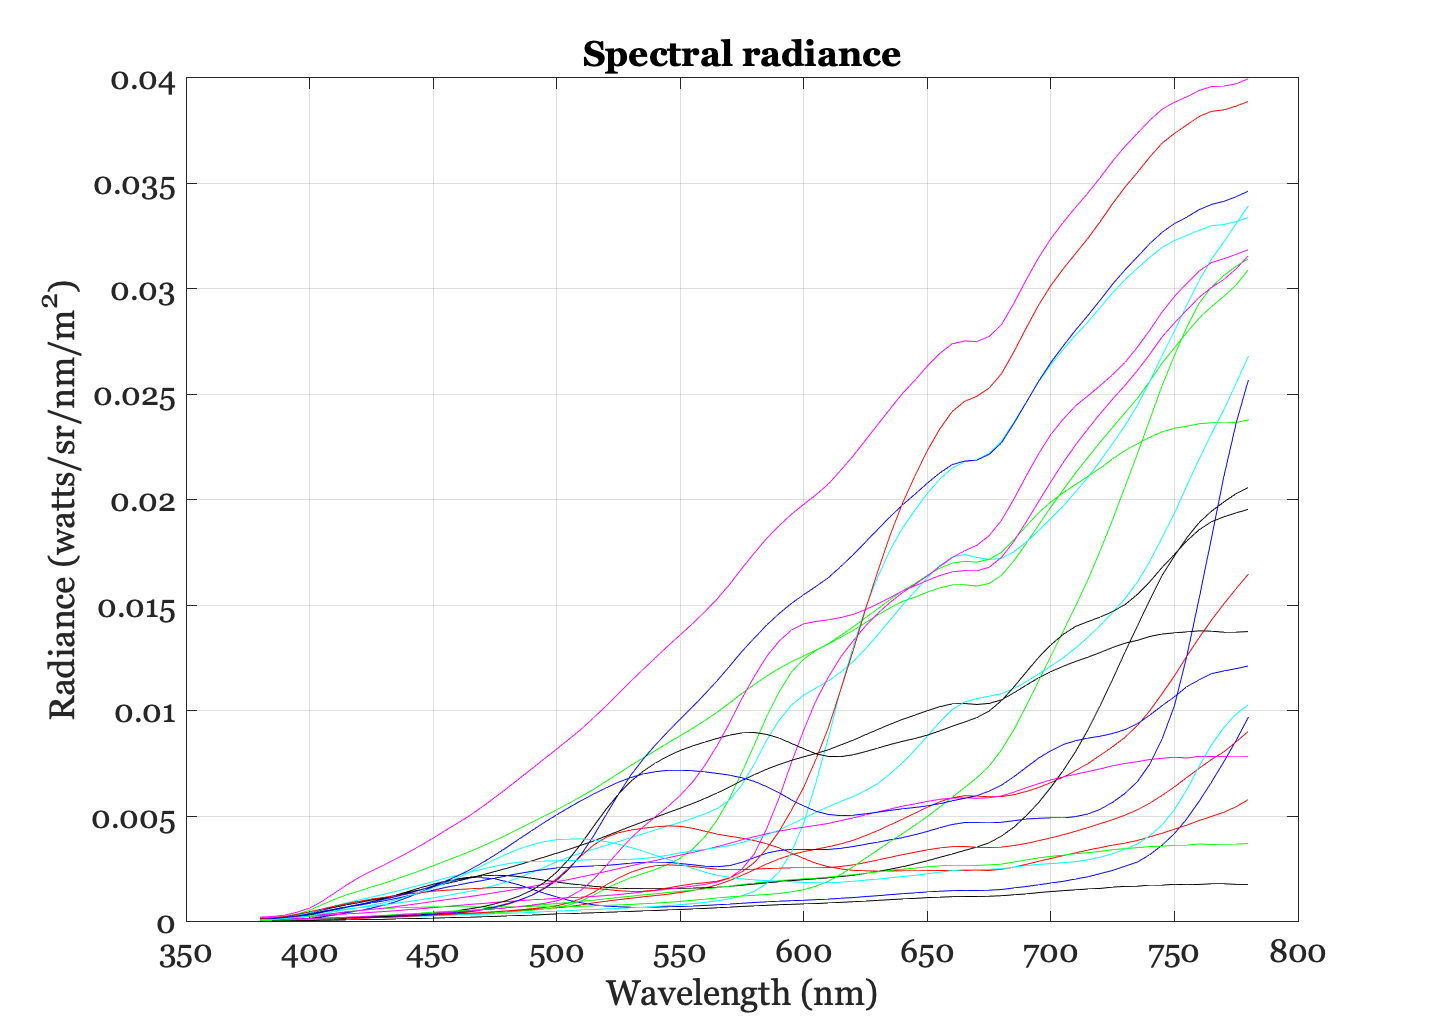

fname = '20201023-mccRadianceData.mat'; % In psych221/projects
[radiance, wave] = ieReadSpectra(fname);
plotRadiance(wave,radiance(:,1:24));    % Illuminant A

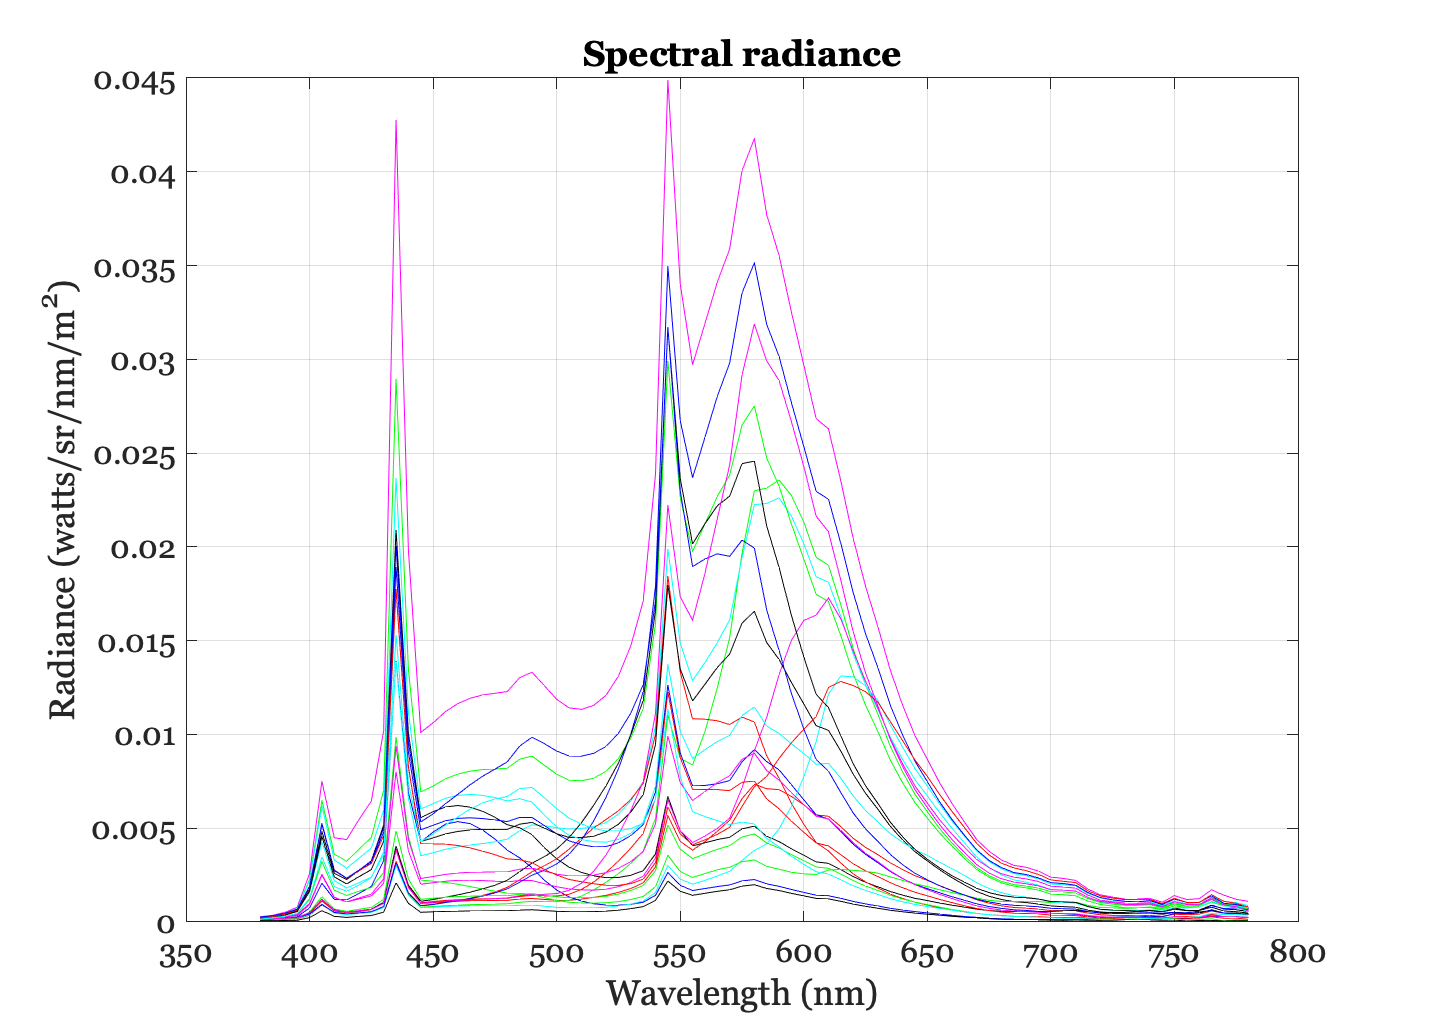

plotRadiance(wave,radiance(:,25:48));   % Illuminant CWF

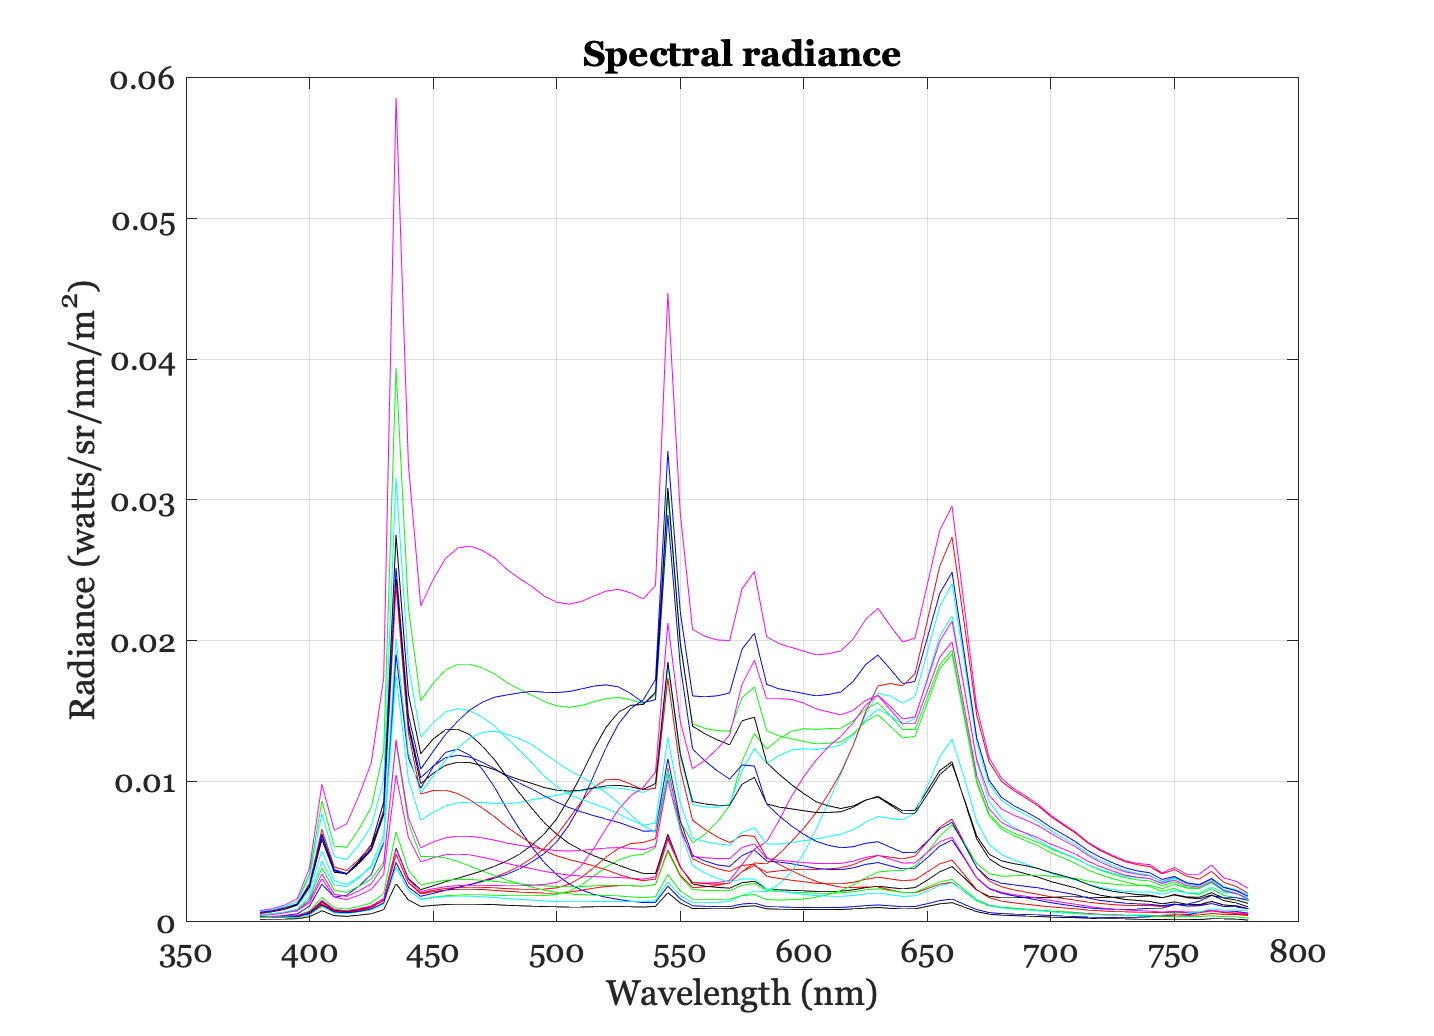

plotRadiance(wave,radiance(:,49:72));   % Illuminant Day